# 
$$c$$


% i = randperm(10)
% rt = i;
ad = "cv/10c/id.mat";
% gfi = gn;
% tic; save(ad,"gfi","-append"); toc % ir

## 
$$10\times100$$


tic; load(ad, 'gfi'); toc % for tc

Elapsed time is 4.064861 seconds.


## 
$$10\times100$$


tic; load(ad, 'c'); toc % for tc

Elapsed time is 11.752128 seconds.


c

c = 2x10 cell array
    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}
    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}


## 
$$tc!,\text{ random 10$$


load(ad, 'rt') % r10, for nt
% ir(1:5)
% save(ad,'rt',"-append") % ir
% gc = gs;
% save(ad,'gc',"-append") % ir
whos("-file",ad)

  Name      Size                  Bytes  Class     Attributes

  c         2x10                 140240  cell                
  cc        2x10                 812240  cell                
  g         2x10              207709560  cell                
  gc        2x10              124918960  cell                
  gfi       2x2                12378192  cell                
  gn        2x2                24023792  cell                
  gs        2x2                24023792  cell                
  gt        2x2                24023792  cell                
  gtc       2x10              124918960  cell                
  idx       1x10                     80  double              
  ir        1x1000                 8000  double              
  rt        1x10                     80  double              
  sh        4x5                   82080  cell                



t1 = c{2,rt(1)}; l = 15

l = 15

A = [t(1:l, :).Variables t1(1:l, end).Variables]

A =   222.5352   47.6375 -122.1402  309.0000  193.0000   47.6421 -122.1387
  224.4341   47.6375 -122.1402  309.0000  193.0000   47.6421 -122.1387
  224.4347   47.6375 -122.1402  309.0000  194.0000   47.6421 -122.1387
  224.7391   47.6375 -122.1402  309.0000  194.0000   47.6421 -122.1387
  225.4136   47.6375 -122.1402  309.0000  195.0000   47.6421 -122.1387
  226.0838   47.6375 -122.1402  309.0000  195.0000   47.6421 -122.1387
  226.4801   47.6375 -122.1402  309.0000  195.0000   47.6421 -122.1387
  227.0464   47.6375 -122.1402  309.0000  196.0000   47.6421 -122.1387
  227.4353   47.6375 -122.1402  309.0000  196.0000   47.6421 -122.1387
  227.8648   47.6375 -122.1402  309.0000  196.0000   47.6421 -122.1387


writematrix(A)

## 
$$nrt%, \text{all random.$$


l = 2*1; nrt = cell(2,l);
for r = 1:2
    nrt{r,l} = c{r,rt(1)}; % ran10
    nrt{r,l-1} = c{r,rt(6)};
    for k = 2:5
        nrt{r,l-1} = [nrt{r,l-1};
                   c{r,rt(k+5)}];
        nrt{r,l} = [nrt{r,l};
                   c{r,rt(k)}];
    end
    % t = nrt{r,l};
    % for col = 1:5 % all random, tr and ts.
    %     nrt{r,2*col-1} = t(sh{3, col},:);
    %     nrt{r,2*col} = t(sh{4, col},:);
    % end
end
nrt

nrt = 2x2 cell array
    {500x6 table}    {500x6 table}
    {500x6 table}    {500x6 table}


k = nrt{1, 1}; k(1,:)

ans = 1x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     222.54      47.637      -122.14      257       186       47.643  


ans = 100x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylongitude
    ________    ________    _________    ______    ______    __________

     222.54      47.637      -122.14      349       215       -122.14  
     224.43      47.637      -122.14      349       216       -122.14  
     224.43      47.637      -122.14      349       216       -122.14  
     224.74      47.637      -122.14      349       217       -122.14  
     225.41      47.637      -122.14      349       217       -122.14  
     226.08      47.637      -122.14      349       218       -122.14  
     226.48      47.637      -122.14      349       218       -122.14  
     227.05      47.637      -122.14      349       218       -122.14  
     227.44      47.637      -122.14      349       219  

l = zeros(10, 2);
for k = 1:10
    t = c{1,rt(k)}.Variables;
    l(k, 1) = t(1, end);
    t = c{2,rt(k)}.Variables;
    l(k, 2) = t(2, end);
end
l

l =    47.6421 -122.1387
   47.6425 -122.1407
   47.6419 -122.1397
   47.6464 -122.1384
   47.6464 -122.1426
   47.6430 -122.1401
   47.6427 -122.1404
   47.6407 -122.1384
   47.6407 -122.1426
   47.6413 -122.1416


c{1,rt(1)}.Variables

ans =   222.5352   47.6375 -122.1402  309.0000  193.0000   47.6421
  224.4341   47.6375 -122.1402  309.0000  193.0000   47.6421
  224.4347   47.6375 -122.1402  309.0000  194.0000   47.6421
  224.7391   47.6375 -122.1402  309.0000  194.0000   47.6421
  225.4136   47.6375 -122.1402  309.0000  195.0000   47.6421
  226.0838   47.6375 -122.1402  309.0000  195.0000   47.6421
  226.4801   47.6375 -122.1402  309.0000  195.0000   47.6421
  227.0464   47.6375 -122.1402  309.0000  196.0000   47.6421
  227.4353   47.6375 -122.1402  309.0000  196.0000   47.6421
  227.8648   47.6375 -122.1402  309.0000  196.0000   47.6421


c{2,rt(k)}.Variables

ans =   222.5352   47.6375 -122.1402  190.0000  205.0000 -122.1416
  224.4341   47.6375 -122.1402  190.0000  206.0000 -122.1416
  224.4347   47.6375 -122.1402  190.0000  207.0000 -122.1416
  224.7391   47.6375 -122.1402  190.0000  206.0000 -122.1416
  225.4136   47.6375 -122.1402  190.0000  206.0000 -122.1416
  226.0838   47.6375 -122.1402  190.0000  207.0000 -122.1416
  226.4801   47.6375 -122.1402  190.0000  207.0000 -122.1416
  227.0464   47.6375 -122.1402  190.0000  207.0000 -122.1416
  227.4353   47.6375 -122.1402  190.0000  208.0000 -122.1416
  227.8648   47.6375 -122.1402  190.0000  208.0000 -122.1416


l

l =    47.6421   47.6421
   47.6425   47.6425
   47.6419   47.6419
   47.6464   47.6464
   47.6464   47.6464
   47.6430   47.6430
   47.6427   47.6427
   47.6407   47.6407
   47.6407   47.6407
   47.6413   47.6413


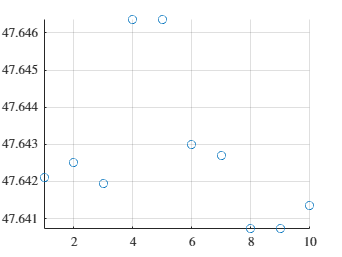

figure;
r = 1;
% co = 1; % 4
% t = nrt{r,co};
scatter(1:10,l(:, 1));
% xlabel('$x$','interpreter','latex');
axis tight
axe();
% hold on;
% plot(sort(predict(gn{r,co},t(:, 1:end-1 ...
%     ).Variables)/fiv))
% plot(predict(gt{r,co},t(:, 1:end-1 ...
% ).Variables)/f)
% hold off;
grid on; % xline(I)

% legend({'data','predictions1' ...
 % ,'p2' ...
 % }, ...
 % 'Location','Best','interpreter','latex')
% title('Longitude','interpreter','latex')

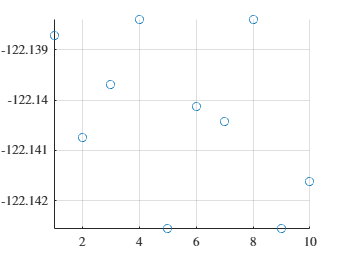

figure;
r = 1;
% co = 1; % 4
% t = nrt{r,co};
scatter(1:10, l(:, 2));
% xlabel('$x$','interpreter','latex');
axis tight
axe();
% hold on;
% plot(sort(predict(gn{r,co},t(:, 1:end-1 ...
%     ).Variables)/fiv))
% plot(predict(gt{r,co},t(:, 1:end-1 ...
% ).Variables)/f)
% hold off;
grid on; 

c{1,rt(8)}

ans = 100x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     222.54      47.637      -122.14      349       215       47.641  
     224.43      47.637      -122.14      349       216       47.641  
     224.43      47.637      -122.14      349       216       47.641  
     224.74      47.637      -122.14      349       217       47.641  
     225.41      47.637      -122.14      349       217       47.641  
     226.08      47.637      -122.14      349       218       47.641  
     226.48      47.637      -122.14      349       218       47.641  
     227.05      47.637      -122.14      349       218       47.641  
     227.44      47.637      -122.14      349       219       47.64

c{2,rt(8)}

ans = 100x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylongitude
    ________    ________    _________    ______    ______    __________

     222.54      47.637      -122.14      349       215       -122.14  
     224.43      47.637      -122.14      349       216       -122.14  
     224.43      47.637      -122.14      349       216       -122.14  
     224.74      47.637      -122.14      349       217       -122.14  
     225.41      47.637      -122.14      349       217       -122.14  
     226.08      47.637      -122.14      349       218       -122.14  
     226.48      47.637      -122.14      349       218       -122.14  
     227.05      47.637      -122.14      349       218       -122.14  
     227.44      47.637      -122.14      349       219  

k = nrt{2, 2}; 

k = 500x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylongitude
    ________    ________    _________    ______    ______    __________

     222.54      47.637      -122.14      309       193       -122.14  
     224.43      47.637      -122.14      309       193       -122.14  
     224.43      47.637      -122.14      309       194       -122.14  
     224.74      47.637      -122.14      309       194       -122.14  
     225.41      47.637      -122.14      309       195       -122.14  
     226.08      47.637      -122.14      309       195       -122.14  
     226.48      47.637      -122.14      309       195       -122.14  
     227.05      47.637      -122.14      309       196       -122.14  
     227.44      47.637      -122.14      309       196    

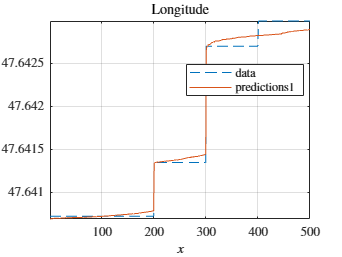

fiv = 1; gn = gfi;
for i = 1
    % :l/2
    figure;
    r = 1; co = 1; % 4
    t = nrt{r,co};
    plot(sort(t(:, end).Variables/fiv),'--');
    xlabel('$x$','interpreter','latex'); axis tight
    axe(); hold on;
    plot(sort(predict(gn{r,co},t(:, 1:end-1 ...
        ).Variables)/fiv))
    % plot(predict(gt{r,co},t(:, 1:end-1 ...
    % ).Variables)/f)
    hold off; grid on; % xline(I)
    legend({'data','predictions1' ...
     % ,'p2' ...
     }, ...
     'Location','Best','interpreter','latex')
    title('Longitude','interpreter','latex')
end

p = cell(2, l);
te = 1; gt = gn;
for r = 1:2
    for co = 1:l/2
        e = 2*co; t = nrt{r,e}; o = e-1;
        p{r, o} = predict(gt{r,o}, t(:, 1: ...
            end-1).Variables)/te;
        p{r, e} = predict(gt{r,e}, t(:, 1: ...
            end-1).Variables)/te;
    end
end
p

p = 2x2 cell array
    {500x1 double}    {500x1 double}
    {500x1 double}    {500x1 double}


% k = p{1, 2}; k(1)
k = p{2, 1}; k(1)

ans = -122.1390

## dikm

d1km = cell(1, l);

## N/10

d = d1km; t = 1;
for co = 1:l
    la = p{1, co}; lo = p{2, co};
    e = 2*ceil(co/2); k = la;
    for i = 1:length(la)
        [k(i), ~] = lldistkm(...
            [nrt{1,e}.Ylatitude(i...
            ) nrt{2,e}.Ylongitude(i...
            )], [la(i) lo(i)]/t);
    end
    d{co} = k*1000;
end
d

d = 1x2 cell array
    {500x1 double}    {500x1 double}


k = d{1}; k(1)

ans = 79.5003

i = 5; e = 2;
[nrt{1,e}.Ylatitude(i...
            ) nrt{2,e}.Ylongitude(i...
            ) la(i) lo(i)]

ans =    47.6421 -122.1387   47.6412 -122.1389


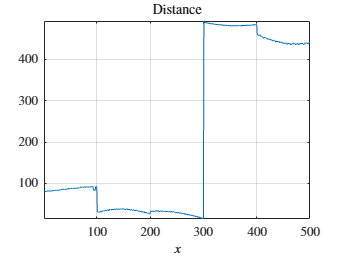

% fiv = 1;
for i = 1
    % :l/2
    figure;
    % r = 2; co = 2; t = nrt{r,co};
    plot(k);
    % plot(sort(t(:, end).Variables/fiv),'--');
    xlabel('$x$','interpreter','latex'); axis tight
    axe();
    % hold on;
    % plot(sort(predict(gc{r,co},t(:, 1:end-1 ...
    %     ).Variables)/fiv))
    % plot(predict(gt{r,co},t(:, 1:end-1 ...
    % ).Variables)/f)
    % hold off;
    grid on; % xline(I)
    % legend({'data','predictions1' ...
     % ,'p2' ...
     % }, ...
     % 'Location','Best','interpreter','latex')
    title('Distance','interpreter','latex')
end

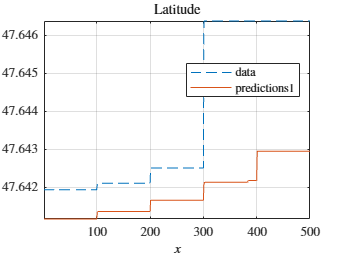

fiv = 1;
for i = 1
    % :l/2
    figure;
    r = 1; co = 2; t = nrt{r,co};
    plot(sort(t(:, end).Variables/fiv),'--');
    xlabel('$x$','interpreter','latex'); axis tight
    axe(); hold on;
    plot(sort(predict(gn{r,co},t(:, 1:end-1 ...
        ).Variables)/fiv))
    % plot(predict(gt{r,co},t(:, 1:end-1 ...
    % ).Variables)/f)
    hold off; grid on; % xline(I)
    legend({'data','predictions1' ...
     % ,'p2' ...
     }, ...
     'Location','Best','interpreter','latex')
    title('Latitude','interpreter','latex')
end

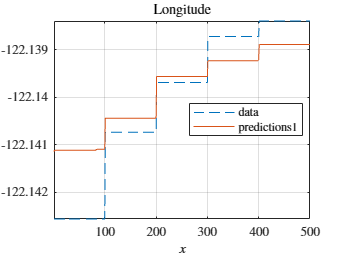

fiv = 1;
for i = 1
    % :l/2
    figure;
    r = 2; t = nrt{r,co};
    plot(sort(t(:, end).Variables/fiv),'--');
    xlabel('$x$','interpreter','latex'); axis tight
    axe(); hold on;
    plot(sort(predict(gn{r,co},t(:, 1:end-1 ...
        ).Variables)/fiv))
    % plot(predict(gt{r,co},t(:, 1:end-1 ...
    % ).Variables)/f)
    hold off; grid on; % xline(I)
    legend({'data','predictions1' ...
     % ,'p2' ...
     }, ...
     'Location','Best','interpreter','latex')
    title('Longitude','interpreter','latex')
end

fid = fopen('cv/10c/n.txt','w');di = d{2};

di =   105.2371
  105.2372
  105.2377
  105.2377
  105.2382
  105.2382
  105.2382
  105.2387
  105.2387
  105.2387


for i=1:500
    fprintf(fid, ['(' num2str(i) ',' num2str( ...
        di(i)) ')']);
end
fclose(fid);
[min(di(:)) max(di(:))]

ans =    32.5324  562.4028


## Without x/10

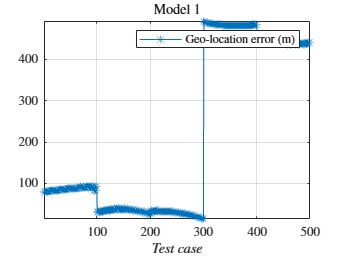

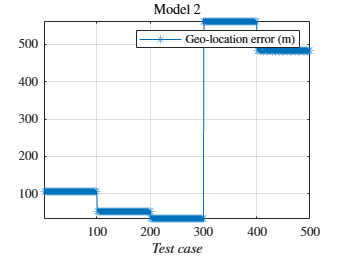

for i = 1:2%l
    figure;
    ndk = d{i}; plot(ndk(:),'-*'); axis tight
    xlabel('$Test$ $case$','interpreter','latex')
    legend('Geo-location error (m)', ...
    'interpreter','latex'); axe(); grid on
    % print(fig,'DistG','-djpeg')
    title(['Model ' num2str(rem(i,2) + ~rem( ...
        i,2)*2)], 'interpreter','latex')
end

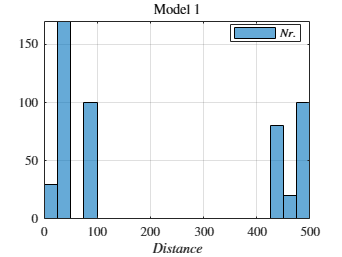

% print(fig,'Ca','-djpeg')
figure; h = histogram(d{1},20);
title('Model 1','interpreter','latex')
xlabel('$Distance$','interpreter','latex'); axe()
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex'); axis tight; grid on

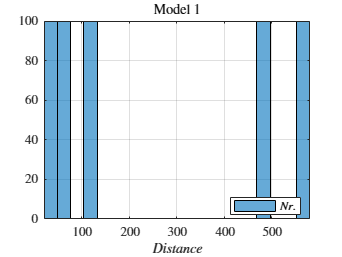

figure; h = histogram(d{2},20);
title('Model 1','interpreter','latex')
xlabel('$Distance$','interpreter','latex'); axe()
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex'); axis tight; grid on